data = readtable('./PROCESSING MAPS/DATA/Al-2024.xlsx');
data.Properties.VariableNames = {'Strain','Strain Rate','T1','T2','T3','T4','T5'}

data = 31×7 table
    Strain    Strain Rate     T1       T2       T3       T4       T5 
    ______    ___________    _____    _____    _____    _____    ____

     NaN           NaN         300      350      400      450     500
     0.1         0.001        76.1       67     41.4     30.4    20.1
     0.1          0.01        89.8       67     54.1     39.5      28
     0.1           0.1       140.9     86.2     64.1     52.9    38.4
     0.1             1         142    107.5     83.3     68.3    51.4
     0.1            10       220.4    141.3    107.7     93.5    75.4
     0.1           100       198.4    175.6    133.1    107.9    86.8
     0.2         0.001        74.4     63.4     40.5     29.2    18.8
     0.2          0.01        88.1     66.4

data(1,:)=[];

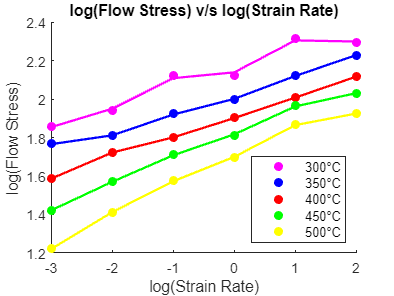

datan= table2array(data);
% 0.5 STRAIN
matrix_at_particular_strain = datan(19:24,2:end);

% STRAIN RATE MATRIX
strain_rate = matrix_at_particular_strain(:,1);
strain_rate_log = log10(strain_rate);

% STRESS MATRIX
stress = matrix_at_particular_strain(:,2:end);
stress_log = log10(stress);

y = zeros(size(stress,1),size(stress,2));

% MATRIX TO REPRESENT COLOURS
Colours = {'m','b','r','g','y',[.8 .5 .9]};
hold on

for r = 1:size(stress,2)
        % SCATTERING DATA POINTS
        Scatter(r) = scatter(strain_rate_log, stress_log(:, r), 'filled', 'MarkerFaceColor', Colours{r});
        
        % CURVE FITTING USING CUBIC SPLINE
        spline_model = fit(log10(strain_rate), log10(stress(:, r)), 'smoothingspline', 'SmoothingParam', 0.99);
        y(:, r) = feval(spline_model, log10(strain_rate));
        
        % PLOTTING
        plot(log10(strain_rate), y(:, r), 'LineWidth', 1.5, 'Color', Colours{r});
end

% LABELLING
ylabel('log(Flow Stress)');
xlabel('log(Strain Rate)');
title('log(Flow Stress) v/s log(Strain Rate)')
legend(Scatter,'300°C','350°C','400°C','450°C','500°C','Location','southeast')
hold on

% FINDING STRAIN RATE SENSITIVITY(m)
m= zeros(size(stress,1),size(stress,2));
for k = 1:size(stress,2)
    for p = 1:size(stress,1)
        spline_model = fit(strain_rate_log, log10(stress(:, k)), 'smoothingspline', 'SmoothingParam', 0.99);
        deriv = differentiate(spline_model, strain_rate_log);
        m(:, k) = deriv;
    end
end

% FINDING EFFICIENCY(e)
e= (2*m./(m+1))*100;
% DEFINING MATRIX FOR A PARTICULAR TEMPERATURE
T= 300:50:500;
% INSTABILITY ZONE
e1= e/200;

% DEFINING SLOPE AS DERIVATIVE OF (m/(m+1)) WRT log(STRAIN RATE)
slope= zeros(size(stress,1),size(stress,2));
for k = 1:size(stress,2)
    for p = 1:size(stress,1)
        spline_model = fit(strain_rate_log, log10(e1(:, k)), 'smoothingspline', 'SmoothingParam', 0.99);
        deriv = differentiate(spline_model, strain_rate_log);
        slope(:, k) = deriv;
    end
end


% Value of The inequality defined for microstructural instability
iz = slope +m; 

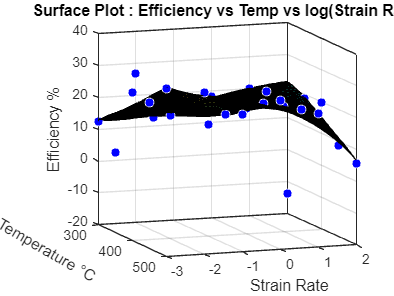

%% PLOTING POWER DISSIPATION MAP

[xData, yData, zData] = prepareSurfaceData( T, strain_rate_log, e );

% SELECTING FIT TYPES AND OPTIONS
ft = fittype( 'loess' );
opts = fitoptions( 'Method', 'LowessFit' );
opts.Normalize = 'on';
opts.Robust = 'Bisquare';
opts.Span = 0.75;

% FITTING THIS MODEL FOR THE GIVEN DATA
[fitresult, ~] = fit( [xData, yData], zData, ft, opts );

% PLOTTING POWER DISSIPATION MAP.
figure( 'Name', 'Power Dissipation Map' );
plot( fitresult, [xData, yData], zData, 'Style', 'Surface' );

% LABELING
xlabel( 'Temperature °C ', 'Interpreter', 'none' );
ylabel( 'Strain Rate', 'Interpreter', 'none' );
zlabel('Efficiency %')
view([70 10]);
set(get(gca,'xlabel'), 'Rotation',-30);
title('Surface Plot : Efficiency vs Temp vs log(Strain Rate)');

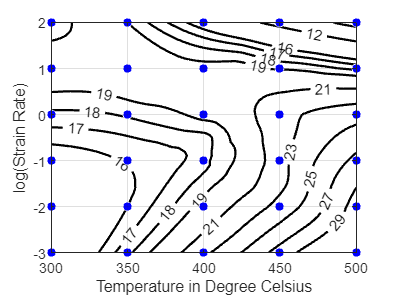

%% 2-D CONTOUR MAPS
[xData, yData, zData] = prepareSurfaceData( T, strain_rate_log, e );

% SELECTING FIT TYPES AND OPTIONS
ft = fittype( 'loess' );
opts = fitoptions( 'Method', 'LowessFit' );
opts.Normalize = 'on';
opts.Robust = 'Bisquare';
opts.Span = 0.75;

% FITTING THIS MODEL FOR THE GIVEN DATA
[fitresult, ~] = fit( [xData, yData], zData, ft, opts );


% PLOTTING 2-D CONTOUR MAPS
figure( 'Name', 'untitled fit 1' );
h=plot( fitresult, [xData, yData], zData, 'Style', 'Contour' );

% LABELING
xlabel( 'Temperature in Degree Celsius', 'Interpreter', 'none' );
ylabel( 'log(Strain Rate)', 'Interpreter', 'none' );
grid on
set(h(1),'ShowText','on','LabelSpacing',144)
set(h(1),'LineWidth',1.5,'Fill','off');
set(h(1),'LevelList',[4,8,12,16,17,18,19,21,23,25,27,29])
saveas(gcf,'POWER_DISSIPATION_MAP.jpg')

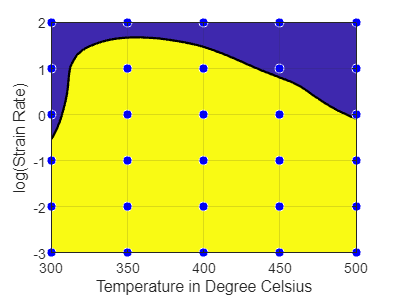

%% INSTABILITY MAPS
[xData, yData, zData] = prepareSurfaceData( T, strain_rate_log, iz );

% SELECTING FIT TYPES AND OPTIONS
ft = fittype( 'loess' );
opts = fitoptions( 'Method', 'LowessFit' );
opts.Normalize = 'on';
opts.Robust = 'Bisquare';
opts.Span = 0.75;

% FITTING THIS MODEL FOR THE GIVEN DATA
[fitresult, gof] = fit( [xData, yData], zData, ft, opts );

% PLOTTING INSTABILITY MAP
figure( 'Name', 'untitled fit 1' );
w=plot( fitresult, [xData, yData], zData, 'Style', 'Contour' );

% LABELING
xlabel( 'Temperature in Degree Celsius', 'Interpreter', 'none' );
ylabel( 'log(Strain Rate)', 'Interpreter', 'none' );
grid on
set(w(1),'LineWidth',1.5,'LevelStep',2);
fig = gcf;
saveas(gcf,'INSTABILITITY_MAP.jpg')

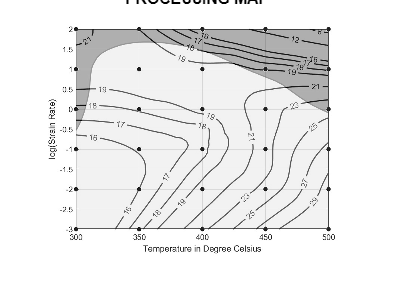

%%https://in.mathworks.com/help/curvefit/fit-smooth-surfaces-to-investigate-fuel-efficiency.% BASIC IMAGE PROCESSING : SUPERIMPOSE
fig1 = imread('POWER_DISSIPATION_MAP.jpg');
fig2 = imread('INSTABILITITY_MAP.jpg');
fusionimage=imfuse(fig1,fig2,'falsecolor','Scaling','joint');
op=rgb2gray(fusionimage);
op= imresize(op,[1968 2622]);
imshow(op)
title('PROCESSING MAP')